% MULTIPLE TIME SERIES --- combine ctrl and cup data
%   Organize folders as Parent\[ctrl; cupr]\[cell 1; cell 2; etc]
%   Requires the following functions to be called:
%       parseFolder.m - runs Analyze_Time_Series on the timepoint files in
%           each condition folder
%       Analyze_Time_Series.m - creates xmlstructs and calculates
%           lengths,intersections, etc on all timepoint files in each cell
%           folder
%       parseXML_SingleCell.m - creates xmlstruct
%       calcIntersectionsXMLtimepoint.m - analyzes xmlstruct
%       calcLengthChanges.m - analyzes the lengths of internodes from the
%           results of calcIntersectionsXMLtimepoint into graph-ready data
%   Cell names indicate ANIMAL NAME, REGION #, AND CELL #
%   e.g. a609_1_r1c6, where a=animal, r=region, c=cell

## Initialization

smoothed = 1; 
% smoothed = input('Do you want to use smoothed traces to calculate lengths? 1 for yes, 0 for no. \n');
useStruct = 1; 
% useStruct = input('Do you want to use previously analyzed xmlstructs? 1 for yes, 0 for no. \n');
% get folder with subfolders of ctrl and cup single cell time series data
maindir = 'D:\GitHubRepos\Call_ParanodalBridge_2022';
addpath(genpath(fullfile(maindir)));
cd(fullfile(maindir,'SingleOLTraces'));
ctrl_dir = dir(fullfile('.', 'ctrl'));
% stbl_dir = dir(fullfile('.', 'stbl'));
ALL=struct;
ALL = parseFolder_singleOL(ctrl_dir,ALL,smoothed,useStruct);
ALL = parseFolder_singleOL(stbl_dir,ALL,smoothed,useStruct);

bsln_dir = dir(fullfile('.','bsln'));
sub_folders = {bsln_dir.name};
sub_folders = sub_folders(~contains(sub_folders,'.') & ~contains(sub_folders,'..'));
dirstr = bsln_dir.folder;
cond_name = dirstr(end-3:end);
ALL.stats.terrRadii.(cond_name) = [];
for k = 1:length(sub_folders)
    cell_name = sub_folders{k}(1:11);
    fprintf('\nParsing folder for cell %s...\n',cell_name);
    dirtemp = [cd,'\',cond_name,'\',sub_folders{k}];
    [ALL.(cond_name).(cell_name).raw, optRadxy, optRadz] = Analyze_Time_Series(dir(dirtemp),smoothed, useStruct);
    ALL.stats.terrRadii.(cond_name) = [ALL.stats.terrRadii.(cond_name); optRadxy, optRadz];
end

ctrl2_dir = dir(fullfile('.','ctrl2'));
sub_folders = {ctrl2_dir.name};
sub_folders = sub_folders(~contains(sub_folders,'.') & ~contains(sub_folders,'..'));
cond_name = 'ctrl';
for k = 1:length(sub_folders)
    cell_name = sub_folders{k}(1:11);
    fprintf('\nParsing folder for cell %s...\n',cell_name);
    dirtemp = [cd,'\','ctrl2','\',sub_folders{k}];
    [ALL.(cond_name).(cell_name).raw, optRadxy, optRadz] = Analyze_Time_Series(dir(dirtemp),smoothed, useStruct);
    ALL.stats.terrRadii.(cond_name) = [ALL.stats.terrRadii.(cond_name); optRadxy, optRadz];
end

## layer II/III

maindir = 'D:\GitHubRepos\Call_ParanodalBridge_2022';
addpath(genpath(fullfile(maindir)));
cd(fullfile(maindir,'SingleOLTraces'));
vis_dir = dir(fullfile('.', 'L2_3'));
% load('ALL_20211109.mat')

sub_folders = {vis_dir.name};
sub_folders = sub_folders(~contains(sub_folders,'.') & ~contains(sub_folders,'..'));
dirstr = vis_dir.folder;
cond_name = dirstr(end-3:end);
ALL.stats.terrRadii.(cond_name) = [];
for k = 1:length(sub_folders)
    cell_name = sub_folders{k}(1:11);
    fprintf('\nParsing folder for cell %s...\n',cell_name);
    dirtemp = [cd,'\',cond_name,'\',sub_folders{k}];
    [ALL.(cond_name).(cell_name).raw, optRadxy, optRadz] = Analyze_Time_Series(dir(dirtemp),1, 1);
    ALL.stats.terrRadii.(cond_name) = [ALL.stats.terrRadii.(cond_name); optRadxy, optRadz];
end

## layer I visual cortex


Parsing folder for cell a202_8_r1c1...



Creating xmlstruct for timepoint d14...


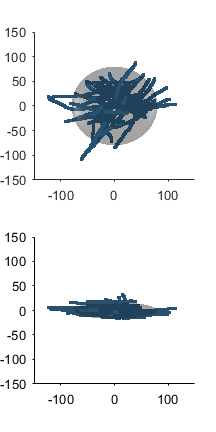

Finished.



Parsing folder for cell a202_8_r2c2...



Creating xmlstruct for timepoint d14...


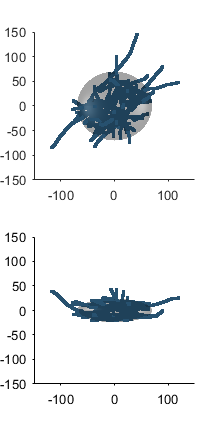

Finished.



Parsing folder for cell a202_8_r3c3...



Creating xmlstruct for timepoint d14...


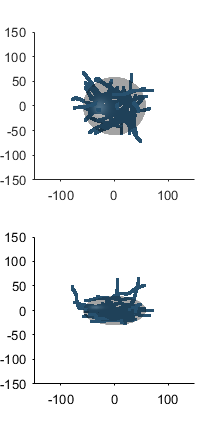

Finished.



Parsing folder for cell a202_9_r1c1...



Creating xmlstruct for timepoint d14...


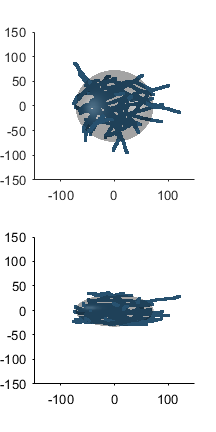

Finished.



Parsing folder for cell a202_9_r2c2...



Creating xmlstruct for timepoint d14...


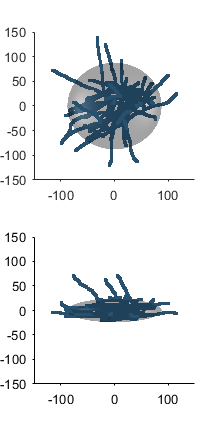

Finished.



Parsing folder for cell a203_0_r1c1...



Creating xmlstruct for timepoint d14...


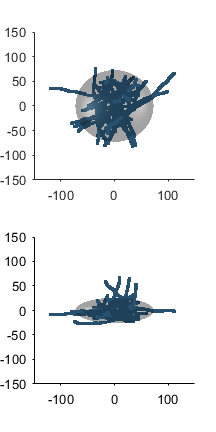

Finished.



Parsing folder for cell a203_0_r1c4...



Creating xmlstruct for timepoint d14...


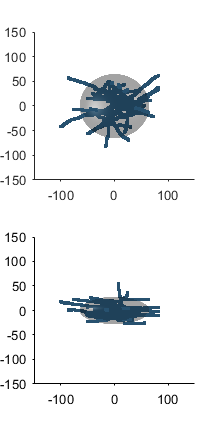

Finished.


maindir = 'D:\GitHubRepos\Call_ParanodalBridge_2022';
addpath(genpath(fullfile(maindir)));
cd(fullfile(maindir,'SingleOLTraces'));
vis_dir = dir(fullfile('.', 'visL1'));
% load('ALL_20211109.mat')

sub_folders = {vis_dir.name};
sub_folders = sub_folders(~contains(sub_folders,'.') & ~contains(sub_folders,'..'));
dirstr = vis_dir.folder;
cond_name = dirstr(end-4:end);
ALL.stats.terrRadii.(cond_name) = [];
for k = 1:length(sub_folders)
    cell_name = sub_folders{k}(1:11);
    fprintf('\nParsing folder for cell %s...\n',cell_name);
    dirtemp = [cd,'\',cond_name,'\',sub_folders{k}];
    [ALL.(cond_name).(cell_name).raw, optRadxy, optRadz] = Analyze_Time_Series(dir(dirtemp),1, 1);
    ALL.stats.terrRadii.(cond_name) = [ALL.stats.terrRadii.(cond_name); optRadxy, optRadz];
end